clear all
load("src\zadanie_06.mat")

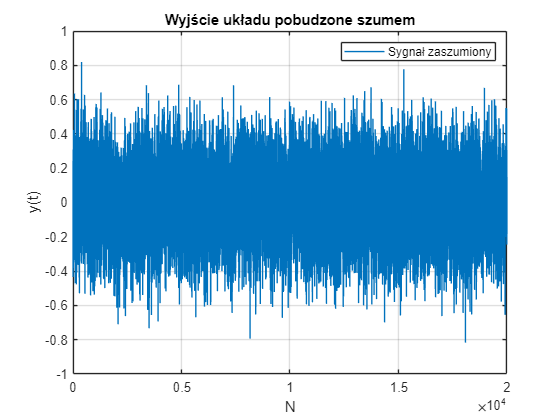

figure
plot(y)
title('Wyjście układu pobudzone szumem')
legend('Sygnał zaszumiony')
xlabel('N')
ylabel('y(t)')
grid on

Znajdowanie minimum L-funkcji:

handle = @(th) l_fun(th, y, A, B, G, C)

handle = function_handle with value:
    @(th)l_fun(th,y,A,B,G,C)



lb = [0,0];
ub = [3,3];
a = [];
b = [];
Aeq = [];
beq = [];
x0 = [0, 0]

x0 =      0     0


[theta_min, min_value, ~, ~, ~, ~, H] = fmincon(handle,x0,a,b,Aeq,beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta_min =     1.9955    0.1999


min_value = -1.0998

H =     0.0051    0.0485
    0.0485   48.0129


Hesjan oraz oszacowanie błędu:

H

H =     0.0051    0.0485
    0.0485   48.0129


S_theta_e = inv(H)

S_theta_e =   197.0604   -0.1989
   -0.1989    0.0210


Stworzenie wykresu L-funkcji oraz wykresu poziomicowego:

th_1 = 0:0.1:3;
th_2 = 0:0.1:3;
Z = zeros(length(th_1), length(th_1));

[X,Y] = meshgrid(th_1,th_2);

for i = 1:length(th_1)
    for j = 1:length(th_2)
        Z(i, j) = handle([X(i, j), Y(i, j)]);
    end
end

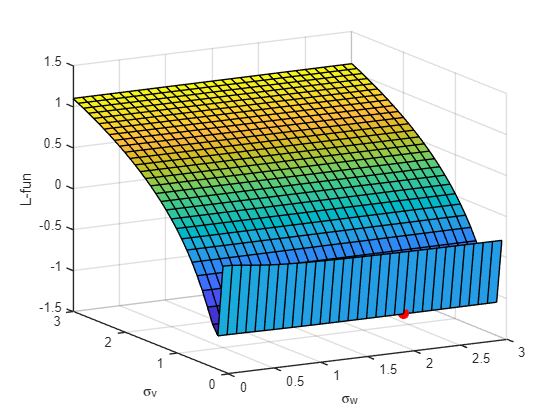

figure
hold on
surf(X,Y,Z)
plot3(theta_min(1), theta_min(2), min_value, '.r', MarkerSize=25)
hold off
xlabel('\sigma_w')
ylabel('\sigma_v')
zlabel('L-fun')
grid on

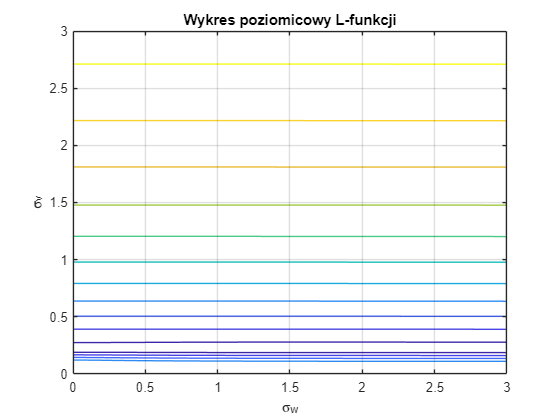


figure
contour(X, Y, Z)
title('Wykres poziomicowy L-funkcji')
xlabel('\sigma_w')
ylabel('\sigma_v')
grid on

Tworzenie sygnału sterującego:

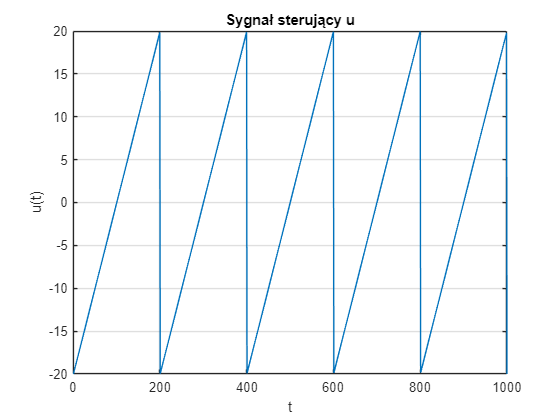

t = linspace(0, 10, 1000);
n = length(t);
f = 0.5;
u = 20 * sawtooth(2*pi*f*t);

figure
plot(u)
title('Sygnał sterujący u')
xlabel('t')
ylabel('u(t)')
grid on

Dodanie szumu procesowego, pomiarowego oraz obliczenie wyjścia ze zmiennymi stanu:

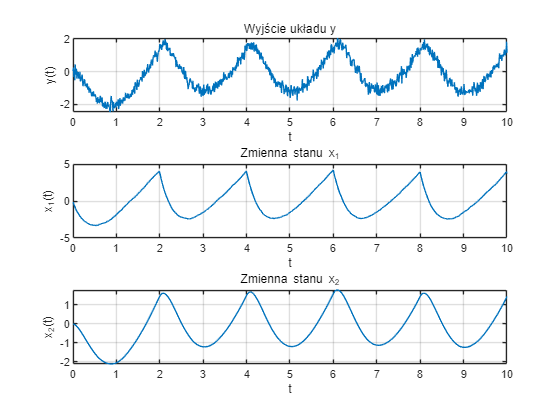

x = zeros(2, n);
y2 = zeros(1, n);
w = zeros(2, n);
v = zeros(1, n);

x(1:2, 1) = [0; 0];
for k = 1:n
    w(:, k) = theta_min(1, 1) * randn(2, 1);
    v(k) = theta_min(1, 2) * randn(1, 1);
    y2(k) = C * x(:, k) + v(k);
    x(:, k + 1) = A * x(:, k) + B * u(k) + G*w(:, k);
end

x = x';
y2 = y2';

figure
subplot(3, 1, 1)
plot(t, y2)
subtitle('Wyjście układu y')
xlabel('t')
ylabel('y(t)')
grid on

subplot(3, 1, 2)
plot(t, x(2:end, 1))
subtitle('Zmienna stanu x_1')
xlabel('t')
ylabel('x_{1}(t)')
grid on

subplot(3, 1, 3)
plot(t, x(2:end, 2))
subtitle('Zmienna stanu x_2')
xlabel('t')
ylabel('x_{2}(t)')
grid on

Zastosowanie filtru kalmana:

[x_e, y_e] = kalman_filter(theta_min, y2, u, A, B, G, C);

Uzyskane wyniki oraz błędy:

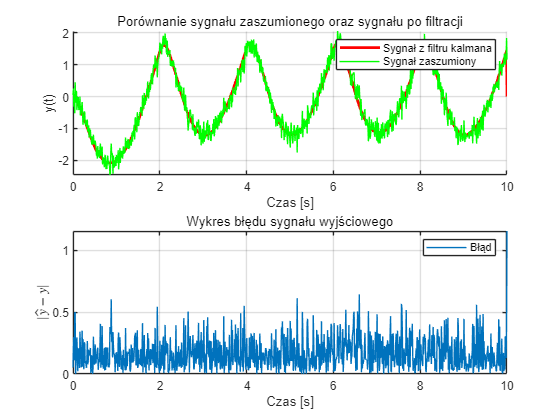

error_y = abs(y2 - y_e);

figure
subplot(2, 1, 1)
hold on
plot(t, y_e, 'r', LineWidth=2)
plot(t, y2, 'g')
hold off
subtitle('Porównanie sygnału zaszumionego oraz sygnału po filtracji')
legend('Sygnał z filtru kalmana', 'Sygnał zaszumiony')
xlabel('Czas [s]')
ylabel('y(t)')
grid on

subplot(2, 1, 2)
plot(t, error_y)
subtitle('Wykres błędu sygnału wyjściowego')
legend('Błąd')
xlabel('Czas [s]')
ylabel('$| \hat{y} - y |$', Interpreter='latex')
grid on

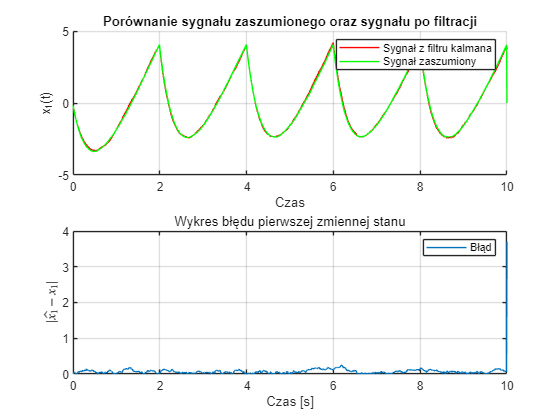

error_x1 = abs(x_e(:, 1) - x(2:end, 1));

figure
subplot(2, 1, 1)
hold on
plot(t, x(2:end, 1), 'r')
plot(t, x_e(:, 1), 'g')
hold off
title('Porównanie sygnału zaszumionego oraz sygnału po filtracji')
legend('Sygnał z filtru kalmana', 'Sygnał zaszumiony')
xlabel('Czas')
ylabel('x_1(t)')
grid on

subplot(2, 1, 2)
plot(t, error_x1)
subtitle('Wykres błędu pierwszej zmiennej stanu')
legend('Błąd')
xlabel('Czas [s]')
ylabel('$| \hat{x_1} - x_1 |$', Interpreter='latex')
grid on

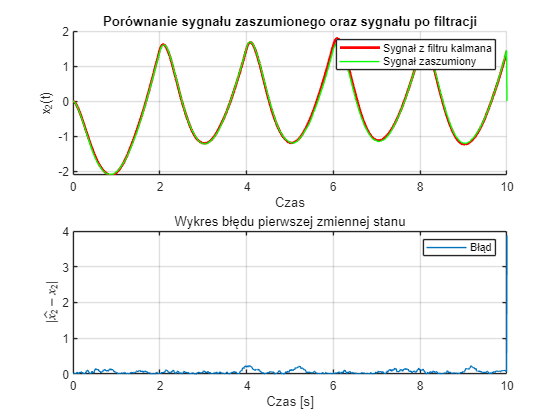

error_x2 = abs(x_e(:, 2) - x(2:end, 2));

figure
subplot(2, 1, 1)
hold on
plot(t, x(2:end, 2), 'r', LineWidth=2)
plot(t, x_e(:, 2), 'g')
hold off
title('Porównanie sygnału zaszumionego oraz sygnału po filtracji')
legend('Sygnał z filtru kalmana', 'Sygnał zaszumiony')
xlabel('Czas')
ylabel('x_2(t)')
grid on

subplot(2, 1, 2)
plot(t, error_x1)
subtitle('Wykres błędu pierwszej zmiennej stanu')
legend('Błąd')
xlabel('Czas [s]')
ylabel('$| \hat{x_2} - x_2 |$', Interpreter='latex')
grid on

function q=l_fun(th, y, A, B, G, C)

[nx, ~] = size(A);
N = length(y);
th = th.^2;
q = 0;
m = zeros(nx, 1);
S = zeros(nx, nx);
u = 0;
for k = 1:N - 1
   m = A*m + B*u;
   S = A*S*A' + (G*G') * th(1);
   W = th(2) + C*S*C';
   e = y(k + 1) - C*m;
   q = (k - 1) * q/k + (e*e/W + log(W))/k;
   S = S - (S*(C' * C)*S)/W;
   m = m+S*C'*e/th(2);
end
q = 0.5 * q;
end


function [x_e, y_e] = kalman_filter(th, y, u, A, B, G, C)

[nx, ~] = size(A);
N = length(y);
th = th.^2;
m = zeros(nx, 1);
S = zeros(nx, nx);
x_e = zeros(N, nx);
y_e = zeros(N, 1);
for k = 1:N - 1
   m = A*m + B*u(k);
   S = A*S*A' + (G*G') * th(1);
   W = th(2) + C*S*C';
   e = y(k + 1) - C*m;
   S = S - (S*(C' * C)*S)/W;
   m = m+S*C'*e/th(2);
   x_e(k, :) = m;
   y_e(k) = C*m;
end
end